direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;
nlinks = length(s.geometry.linklengths);

s = ensure_connection_and_metric(s); % required for create_grids
s = create_grids(s)

s = struct with fields:
      geometry: [1×1 struct]
          noop: 1
         n_dim: 1
        visual: [1×1 struct]
       physics: [1×1 struct]
             A: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
        metric: @(alpha1)LowRE_dissipation_metric(s.geometry,s.physics,[alpha1])
    grid_range: [-3.1000 3.1000]
       density: [1×1 struct]
      tic_locs: [1×1 struct]
         A_num: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
          grid: [1×1 struct]


a_grid = s.grid.eval{1};
adot_grid = s.grid.eval{1}*0.1;

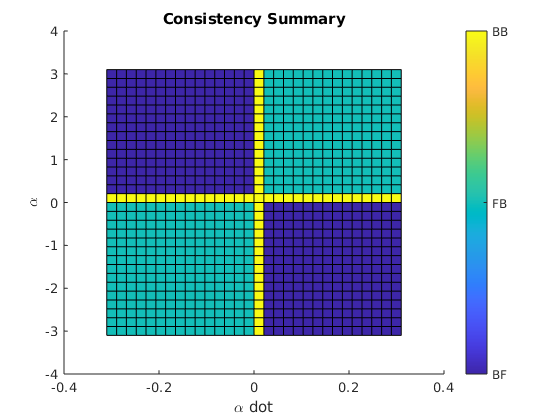

% find which system is consistent when
[system_map, count] = identify_piecewise_system(s, adot_grid);

% look at symmetry and missing/redundant areas
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
surface(adot_grid, a_grid, system_map);
colorbar('Ticks',[1, 2, 3, 4],...
         'TickLabels',direction_names)

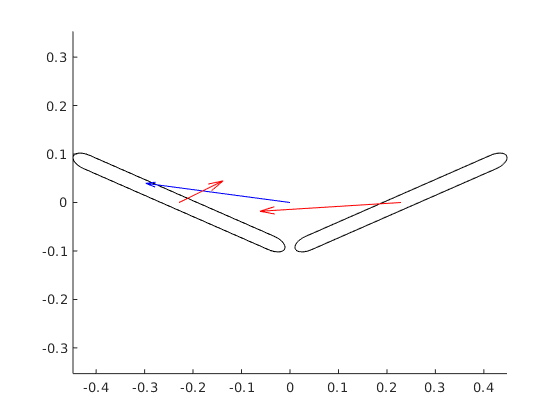

% get a body velocity
i = 20; j = 30;
bvel = apply_piecewise_system(s, system_map, adot_grid, i, j);

% get link velocities
lvel = zeros(nlinks, 3); % 3 is x y theta

% get Jfull(alpha)
[~, ~, J_full, ~, ~] = N_link_chain(s.geometry, a_grid(i));

for link = 1:nlinks
    lvel(link, :) = J_full{link} * [bvel; adot_grid(j)];
end

% plot
velocity_diagram(s, lvel, bvel, a_grid(i), adot_grid(j), 0, 0);

% animate testing
% inputs needed:
% a path alpha(t)
% a function that tells you gdot given g and t
% (see whiteboard snapshot from 1/22/2020 and p30 of notebook)
% knowledge of how to use ODE45
% (then later compare to doing it myself using product integral)

% next step: make apply_piecewise_system take a specific a and adot
% and then interpolate if needed

function [a] = gait(t)
    a = sin(t);

s = struct with fields:
      geometry: [1×1 struct]
          noop: 1
         n_dim: 1
        visual: [1×1 struct]
       physics: [1×1 struct]
             A: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
        metric: @(alpha1)LowRE_dissipation_metric(s.geometry,s.physics,[alpha1])
    grid_range: [-3.1000 3.1000]
       density: [1×1 struct]
      tic_locs: [1×1 struct]
         A_num: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
          grid: [1×1 struct]


end

function [adot] = gait_change(t)
    adot = cos(t);
end

function [gdot] = calc_gdot(t, g)
    gdot = TeLg(g) * apply_piecewise_system(s, system_map, a, adot, i, j);
end